**Course:                **Industrielle & Medizinische Bildverarbeitung

**Insitute:                **Salzburg University of Applied Sciences  

**Author:                 **Niko Jozic 

**Departement:       **Information Technology & System-Management

# 3.1

clc, clear variables, close all;
addpath('.\Petri');
petri = {};

for i = 1:7   

    n = sprintf('petri%d',i);
    [img, map] = dicomread(n);
    
    petri{i}.inf = dicominfo(n);
    petri{i}.img = img;
    petri{i}.map = map;
    
    date = petri{i}.inf.AcquisitionDate;
    YY = str2num(date(1:4));
    DD = str2num(date(5:6));
    MM = str2num(date(7:8));
    
    time = petri{i}.inf.AcquisitionTime;
    hh = str2num(time(1:2));
    mm = str2num(time(3:4));
    ss = str2num(time(5:6));
    
    timestamp = [YY DD MM hh mm ss];
    
    N(i) = sum(sum(petri{i}.img));
    
    petri{i}.timestamp = timestamp;
       
end

for i=1:6
    delta_t = etime(petri{i+1}.timestamp,petri{i}.timestamp);
    lambda(i) =  -log(N(i+1)/N(i))/delta_t;   
end

t_half = (log(2)/mean(lambda)/3600);

fprintf('According to the calculation, the half-life is %.3g hours.', t_half);

According to the calculation, the half-life is 6.06 hours.

# 3.2

img1 = imread('DSA1.jpg');
img2 = imread('DSA2.jpg');
img3 = img1-img2;

figure
subplot(131);
imshow(img1,[]);
title('IMG1');

subplot(132);
imshow(img2,[]);
title('IMG2');

subplot(133);
imshow(img3,[]);
title('IMG1-IMG2');
colormap(hot);

# 3.3.a

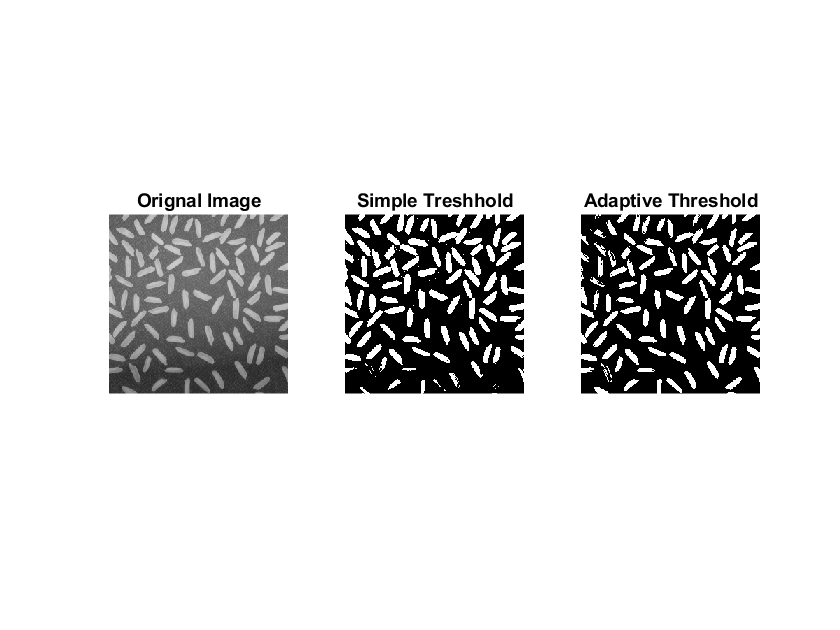

img = imread('rice.png');
s = 80; 
t = [-2:0.1:1.4];

subplot(131);
imshow(img);
title('Orignal Image');

BW = imbinarize(img);

subplot(132);
imshow(BW,[]);
title('Simple Treshhold');

subplot(133)
for i=1:1:numel(t)
    seg_img = MyAdaptiveThresholding(img, s, t(i));
    imshow(seg_img, []);
    title('Adaptive Threshold');
    pause(0.01);
end

# 3.3.b & 3.3.c

The threshold value calculation according to Otsu is used to reduce a grayscale image to a binary image. With this method, the algorithm assumes that the image contains two classes (foreground and background pixels). From this, the optimal threshold value can then be calculated which divides the two classes. The combined spread is therefore minimal or equivalent with a maximum variance (Source: Wikpedia).

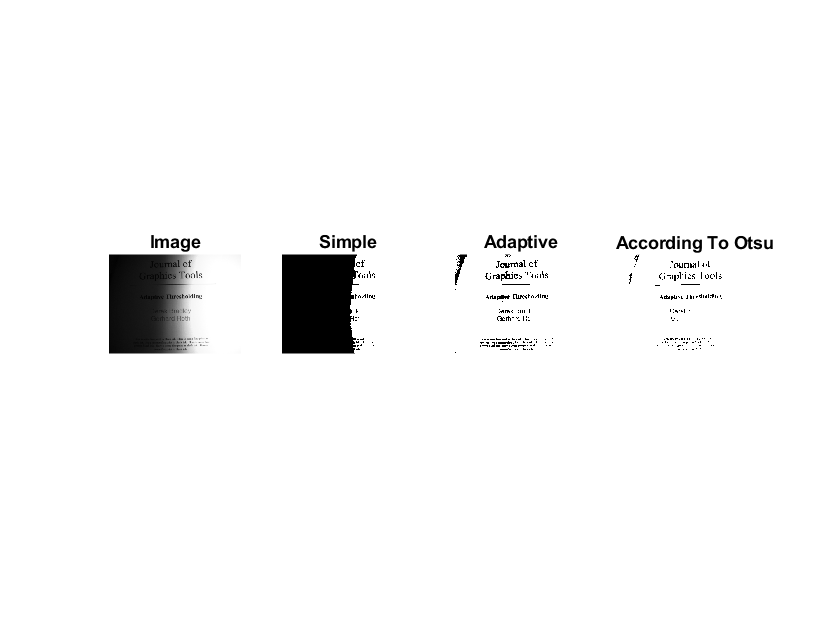

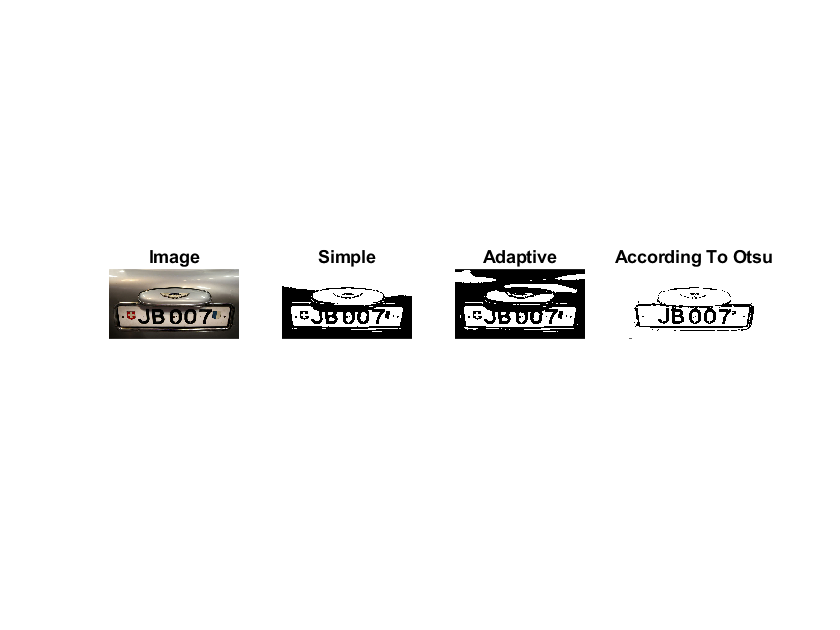

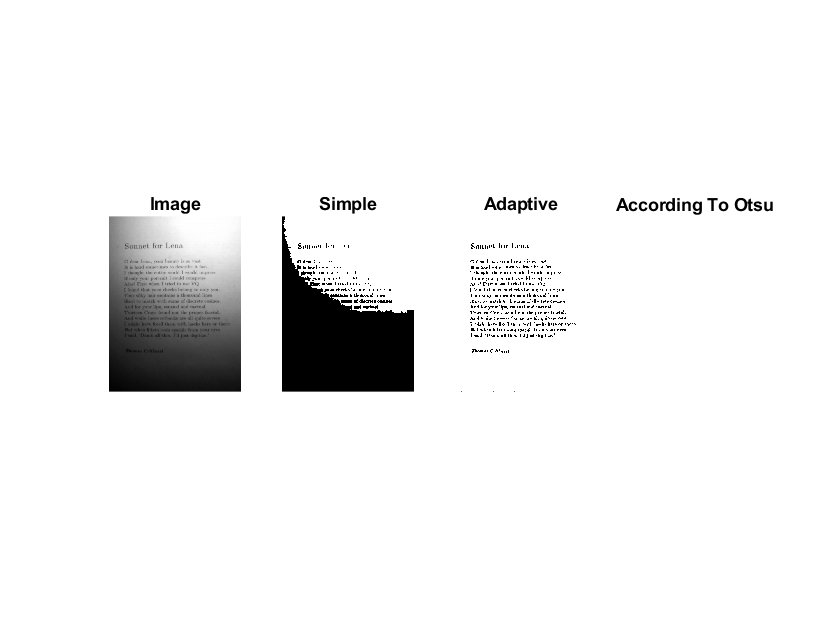

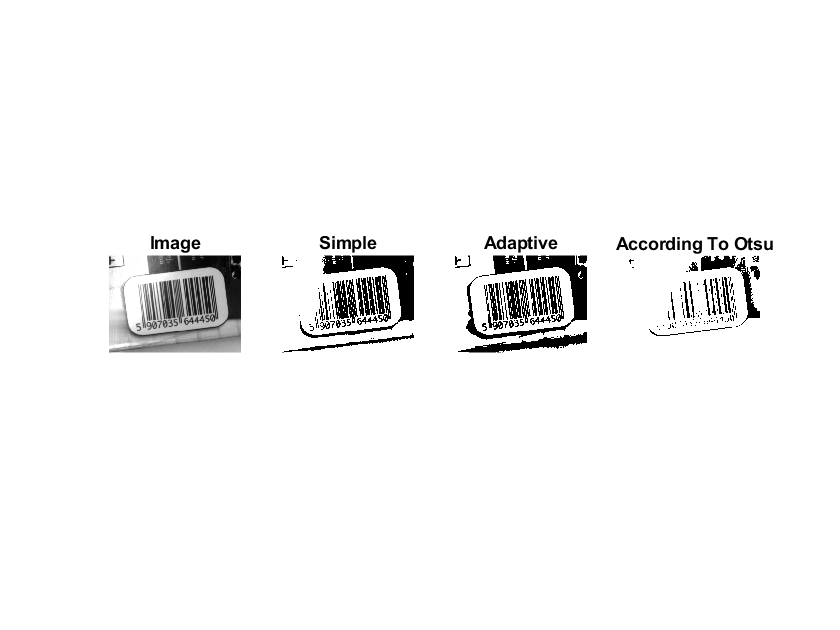

clc, clear variables, close all;

img_names = {'journal.png','jb007.jpg','sonnet.png', 'barcode.png'};
s = [30, 80, 6, 25];
t = [0.7, 1.2, 0.925, 1.0];
img ={};

for i=1:4
    img{i}.read = imread(img_names{i});
end

for i=1:numel(img)
    
    figure;
    subplot(141);
    imshow(img{i}.read,[]);
    title('Image');
    
    subplot(142);
    try
        BW = imbinarize(img{i}.read);
        imshow(BW,[]);
    catch
        BW = rgb2gray(img{i}.read);
        BW = imbinarize(BW);
        imshow(BW,[]);
    end
    title('Simple');
    
    subplot(143);
    try
        img{i}.segimg = MyAdaptiveThresholding(img{i}.read, s(i), t(i));
        imshow(img{i}.segimg);
    catch
        img{i}.segimg = MyAdaptiveThresholding(rgb2gray(img{i}.read), s(i), t(i));
        imshow(img{i}.segimg,[]);
    end
    title('Adaptive');
    
    subplot(144);
    level = graythresh(img{i}.read);
    try
        img{i}.segimg = MyAdaptiveThresholding(img{i}.read, s(i), level);
        imshow(img{i}.segimg);
    catch
        img{i}.segimg = MyAdaptiveThresholding(rgb2gray(img{i}.read), s(i), level);
        imshow(img{i}.segimg,[]);
    end
    title('According To Otsu');
    
end

# 3.3.d

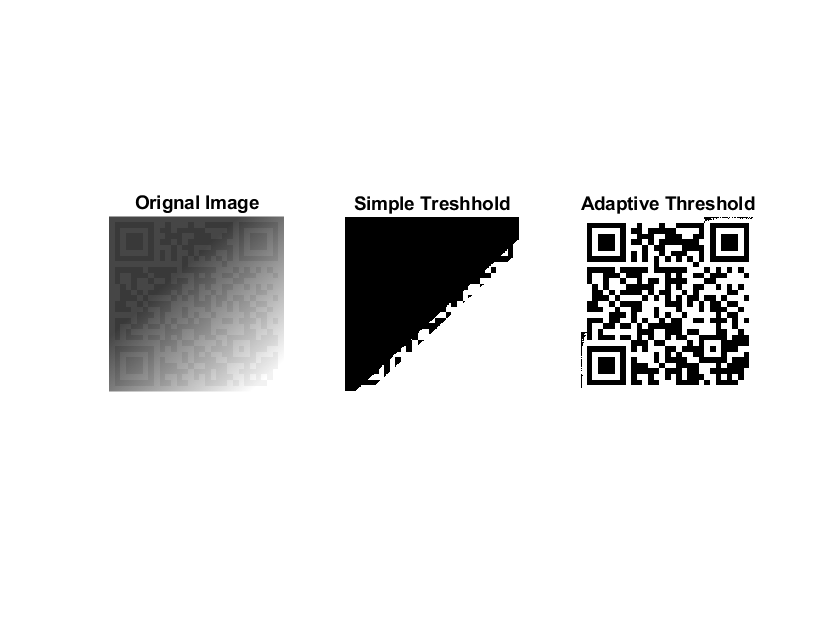

clc, clear variables, close all;

img = imread('suprise.png');
img = rgb2gray(img);
s = 25; 
t = [-2:0.1:1.0];

subplot(131);
imshow(img);
title('Orignal Image');

BW = imbinarize(img);

subplot(132);
imshow(BW,[]);
title('Simple Treshhold');

subplot(133)
for i=1:1:numel(t)
    seg_img = MyAdaptiveThresholding(img, s, t(i));
    imshow(seg_img, []);
    title('Adaptive Threshold');
    pause(0.01);
end


fprintf("Content of the surprise:\nhttps://www.youtube.com/watch?v=Oos4ojutOMM\n");

Content of the surprise:
https://www.youtube.com/watch?v=Oos4ojutOMM
